# Annotated Isosurface Viewer

## Load in data (MRI)

s = load('mri.mat');
data = squeeze(s.D);

% Create isosurface
isovalue = 40;
[faces, vertices] = isosurface(data, isovalue);
voxel_size  = [1 1 3];
vertices    = vertices .* voxel_size;
vertexNormals = isonormals(data,vertices);

% Place into an IsosurfaceModel
isoModel = wt.model.IsosurfaceModel(...
    'Faces',faces,...
    'Vertices',vertices,...
    'VertexNormals',vertexNormals);

## Create the widget

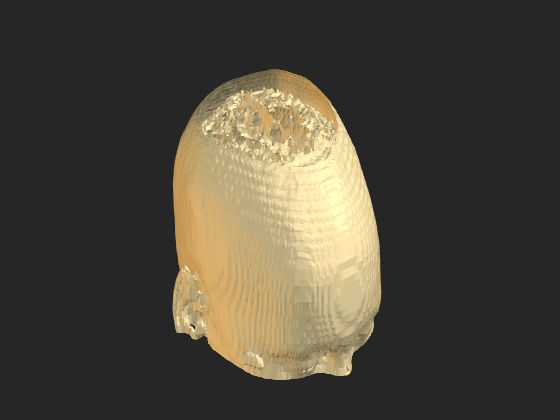

f = uifigure;
g = uigridlayout(f,'ColumnWidth',{'1x'},'RowHeight',{'1x'},'Padding',[0 0 0 0]);
w = wt.AnnotatedIsosurfaceViewer('Parent',g,'IsosurfaceModel',isoModel);
movegui(f,'northwest');

## Add Points Annotation

thisPoints = [
   84.1572   31.2435   80.9678
   47.4634   45.7015   80.9667
   46.5614   77.8666   80.9756
    ];
 thisColor = [.5 .7 .3];
 thisAlpha = .7;
a1 = wt.model.LineAnnotation(...
    'Name','Line 1',...
    'Points',thisPoints,...
    'Color',thisColor,...
    'Alpha',thisAlpha,...
    'IsVisible',true);

w.addAnnotation(a1);

## Add Plane Annotation

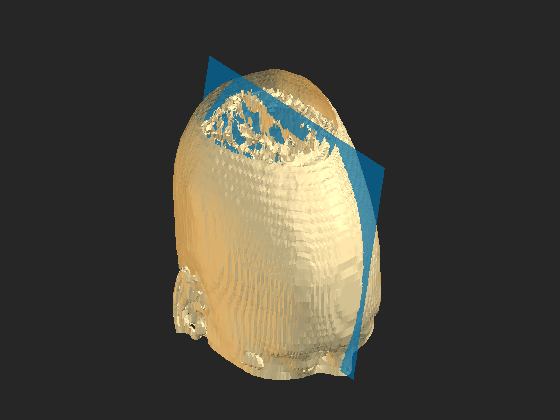

thisPoints = [
   110.6 67.67 77.12
   17.41 72.61 38.27
   20.97 64.07 4.049
   ];
thisColor = [0 0.6000 1];
thisAlpha = .7;
a2 = wt.model.PlaneAnnotation(...
    'Name','Plane 1',...
    'Points',thisPoints,...
    'Color',thisColor,...
    'Alpha',thisAlpha,...
    'IsVisible',true);

w.addAnnotation(a2);

*Copyright 2018-2020 The MathWorks, Inc.*